%% ========================================================================
% EEG Lempel-Ziv Complexity (LZC)
% Eyes-closed EEG | 57 channels
%
% Analyses:
%   1) LZC per subject x channel
%   2) Female vs Male comparison
%   3) Multiple linear regression:
%          LZC ~ FSIQ + Gender + Age
%   4) FDR correction across 57 channels
%   5) Quality-control tests and scalp topographies
%
% INPUT:
%   Files: *_middle_matrix_*.mat
%   Variable inside every file: middleMatrix
%   middleMatrix dimension: [trials x channels x samples]
%
% DEMOGRAPHIC EXCEL COLUMNS:
%   Code, FSIQ, Gender, Age
%
% IMPORTANT:
%   The filenames have this format:
%       _middle_matrix_10.mat
%       _middle_matrix_214.mat
%
%   The code converts them to:
%       CBM00010
%       CBM00214
%
% OUTPUT:
%   LZC_subject_channel.mat
%   LZC_gender_results.xlsx
%   LZC_regression_results.xlsx
%   LZC_qc_summary.xlsx
%   LZC_COMPLETE_RESULTS.mat
%   LZC_mean_topography.png
%   LZC_gender_effect_topography.png
%   LZC_FSIQ_effect_topography.png
% ========================================================================

clear;
clc;
close all;

%% ========================================================================
% 1. PATHS
% ========================================================================

dataFolder = 'C:\assabNEW\subs\';

% مسیر فایل Excel را با مسیر واقعی خودت تنظیم کن
excelFile = 'C:\assabNEW\subsub.xlsx';

% فایل channel locations
locPath = 'C:\kar\matlab\zemestun\loc57.mat';

% اگر EEGLAB در path نیست، مسیر eeglab را اضافه کن
% addpath(genpath('C:\Users\shab\OneDrive\Documents\MATLAB\eeglab2024.0'));

%% ========================================================================
% 2. SETTINGS
% ========================================================================

nChanExpected = 57;

% حداقل تعداد نمونه برای محاسبه‌ی LZC
minSamplesForLZC = 100;

% اگر می‌خواهی فقط مثلاً 10 trial اول استفاده شوند:
% maxTrials = 10;
%
% برای استفاده از تمام trialها:
maxTrials = Inf;

% حداقل تعداد نمونه در هر گروه برای Female vs Male
minNPerGenderGroup = 3;

% حداقل تعداد subject برای regression
minNForRegression = 10;

% آستانه‌ی FDR
alphaFDR = 0.05;

% برای رسم p-value map:
% جلوگیری از مقدار بسیار بزرگ در صورت underflow عددی
maxNegLogPForPlot = 10;

% آیا topography تولید شود؟
makeTopographies = true;

%% ========================================================================
% 3. START MESSAGE
% ========================================================================

fprintf('====================================================\n');

fprintf('        EEG Lempel-Ziv Complexity Analysis\n');

        EEG Lempel-Ziv Complexity Analysis


fprintf('====================================================\n\n');


%% ========================================================================
% 4. LOAD CHANNEL LOCATIONS
% ========================================================================

if ~exist(locPath,'file')
    error('Channel-location file not found:\n%s', locPath);
end

locData = load(locPath);

if isfield(locData,'loc57')
    loc57 = locData.loc57;
else
    error('The file does not contain a variable named loc57.');
end

if ~isstruct(loc57)
    error('loc57 must be an EEGLAB channel-location structure.');
end

if numel(loc57) ~= nChanExpected
    error('loc57 has %d channels, but expected %d.', ...
        numel(loc57), nChanExpected);
end

%% ========================================================================
% 5. LOAD DEMOGRAPHIC DATA
% ========================================================================

fprintf('Loading demographic data...\n');

Loading demographic data...



if ~exist(excelFile,'file')
    error('Demographic Excel file not found:\n%s', excelFile);
end

demo = readtable(excelFile, 'VariableNamingRule', 'preserve');

disp('Columns in demographic table:');

Columns in demographic table:


disp(demo.Properties.VariableNames');

    {'Code'           }
    {'FSIQ'           }
    {'class'          }
    {'VIQ'            }
    {'PIQ'            }
    {'Gender'         }
    {'Age'            }
    {'Education Level'}
    {'Hand preference'}




ID_col     = 'Code';
Gender_col = 'Gender';
Age_col    = 'Age';
FSIQ_col   = 'FSIQ';

requiredColumns = {ID_col, Gender_col, Age_col, FSIQ_col};

for i = 1:numel(requiredColumns)

    if ~ismember(requiredColumns{i}, demo.Properties.VariableNames)

        error('Column "%s" was not found in the Excel file.', ...
            requiredColumns{i});

    end

end

%% ------------------------------------------------------------------------
% Convert Excel IDs to one standard format: CBM#####.
% Examples:
% 10       -> CBM00010
% CBM10    -> CBM00010
% CBM00010 -> CBM00010
%% ------------------------------------------------------------------------

demoCodeOriginal = string(demo.(ID_col));
demoCodeStandard = strings(height(demo),1);

for i = 1:height(demo)

    currentCode = strtrim(demoCodeOriginal(i));

    numberText = regexp(currentCode, '\d+', 'match', 'once');

    if isempty(numberText)
        demoCodeStandard(i) = "";
    else
        demoCodeStandard(i) = sprintf('CBM%05d', ...
            str2double(numberText));
    end

end

demo.CodeStandard = demoCodeStandard;

%% ========================================================================
% 6. FIND EEG FILES
% ========================================================================

files = dir(fullfile(dataFolder, '*_middle_matrix_*.mat'));

fprintf('\nNumber of middle-matrix files found: %d\n', numel(files));


Number of middle-matrix files found: 80



if isempty(files)
    error('No *_middle_matrix_*.mat files found in:\n%s', dataFolder);
end

%% ========================================================================
% 7. PREALLOCATE STORAGE
% ========================================================================

nFiles = numel(files);

LZC_all = nan(nFiles, nChanExpected);

SubjectID = strings(nFiles,1);
GenderRaw = strings(nFiles,1);
GenderStandard = strings(nFiles,1);

Age = nan(nFiles,1);
FSIQ = nan(nFiles,1);

nTrialsUsed = nan(nFiles,1);
nSamplesUsed = nan(nFiles,1);

qc_ChannelLZC_SD = nan(nFiles,1);
qc_SubjectMeanLZC = nan(nFiles,1);

%% ========================================================================
% 8. COMPUTE LZC
% ========================================================================

fprintf('\nCalculating LZC...\n');


Calculating LZC...



for s = 1:nFiles

    filename = files(s).name;

    fprintf('\nSubject %d/%d: %s\n', s, nFiles, filename);

    %% --------------------------------------------------------------------
    % Extract numeric ID from filename:
    % _middle_matrix_10.mat --> CBM00010
    %% --------------------------------------------------------------------

    [~, fileBase, ~] = fileparts(filename);

    idToken = regexp(fileBase, '_middle_matrix_(\d+)$', ...
        'tokens', 'once');

    if isempty(idToken)

        warning('Could not extract subject ID from %s', filename);
        continue;

    end

    subjectNumber = str2double(idToken{1});
    subjectCode = sprintf('CBM%05d', subjectNumber);

    SubjectID(s) = string(subjectCode);

    %% --------------------------------------------------------------------
    % Match subject with demographic Excel table
    %% --------------------------------------------------------------------

    demoRow = find(strcmpi(demo.CodeStandard, SubjectID(s)), 1);

    if isempty(demoRow)

        warning('No demographic data found for subject %s.', subjectCode);
        continue;

    end

    GenderRaw(s) = string(demo.(Gender_col)(demoRow));
    GenderStandard(s) = localStandardizeGender(GenderRaw(s));

    Age(s) = localToDouble(demo.(Age_col)(demoRow));
    FSIQ(s) = localToDouble(demo.(FSIQ_col)(demoRow));

    %% --------------------------------------------------------------------
    % Load middleMatrix
    %% --------------------------------------------------------------------

    filePath = fullfile(dataFolder, filename);

    try
        S = load(filePath);
    catch ME
        warning('Could not load %s:\n%s', filename, ME.message);
        continue;
    end

    if ~isfield(S,'middleMatrix')

        warning('%s does not contain "middleMatrix".', filename);
        continue;

    end

    middleMatrix = double(S.middleMatrix);

    if ndims(middleMatrix) ~= 3

        warning('%s is not a 3D matrix.', filename);
        continue;

    end

    nTrials = size(middleMatrix,1);
    nChanThis = size(middleMatrix,2);
    nSamples = size(middleMatrix,3);

    fprintf('Trials = %d | Channels = %d | Samples = %d\n', ...
        nTrials, nChanThis, nSamples);

    if nChanThis ~= nChanExpected

        warning('Skipping %s: found %d channels, expected %d.', ...
            subjectCode, nChanThis, nChanExpected);
        continue;

    end

    if isfinite(maxTrials)
        nTrialsToUse = min(nTrials, maxTrials);
    else
        nTrialsToUse = nTrials;
    end

    nTrialsUsed(s) = nTrialsToUse;
    nSamplesUsed(s) = nSamples;

    trialLZC = nan(nTrialsToUse, nChanExpected);

    %% --------------------------------------------------------------------
    % Calculate LZC for each trial and each channel
    %% --------------------------------------------------------------------

    for tr = 1:nTrialsToUse

        for ch = 1:nChanExpected

            x = squeeze(middleMatrix(tr,ch,:));
            x = double(x(:));

            % حذف NaN / Inf
            x = x(isfinite(x));

            if numel(x) < minSamplesForLZC
                continue;
            end

            % اگر سیگنال کاملاً ثابت باشد، LZC قابل‌تفسیر نیست
            if std(x) == 0
                continue;
            end

            % Median binarization:
            % بالاتر از median = 1
            % پایین‌تر یا مساوی median = 0
            threshold = median(x);
            binarySignal = x > threshold;

            % اگر فقط صفر یا فقط یک شد، قابل‌استفاده نیست
            if all(binarySignal == binarySignal(1))
                continue;
            end

            trialLZC(tr,ch) = localLZC(binarySignal);

        end

    end

    %% Subject-level mean LZC across valid trials

    LZC_all(s,:) = mean(trialLZC, 1, 'omitnan');

    qc_ChannelLZC_SD(s) = std(LZC_all(s,:), 0, 'omitnan');
    qc_SubjectMeanLZC(s) = mean(LZC_all(s,:), 'omitnan');

    fprintf('Mean LZC = %.6f | SD across channels = %.6f\n', ...
        qc_SubjectMeanLZC(s), qc_ChannelLZC_SD(s));

end


Subject 1/80: _middle_matrix_10.mat


Trials = 21 | Channels = 57 | Samples = 1000


Mean LZC = 0.544438 | SD across channels = 0.009384



Subject 2/80: _middle_matrix_101.mat


Trials = 15 | Channels = 57 | Samples = 1000


Mean LZC = 0.604020 | SD across channels = 0.030476



Subject 3/80: _middle_matrix_103.mat


Trials = 17 | Channels = 57 | Samples = 1000


Mean LZC = 0.589668 | SD across channels = 0.023792



Subject 4/80: _middle_matrix_109.mat


Trials = 22 | Channels = 57 | Samples = 1000


Mean LZC = 0.575663 | SD across channels = 0.034814



Subject 5/80: _middle_matrix_11.mat


Trials = 17 | Channels = 57 | Samples = 1000


Mean LZC = 0.571906 | SD across channels = 0.020991



Subject 6/80: _middle_matrix_110.mat


Trials = 11 | Channels = 57 | Samples = 1000


Mean LZC = 0.542142 | SD across channels = 0.011027



Subject 7/80: _middle_matrix_111.mat


Trials = 24 | Channels = 57 | Samples = 1000


Mean LZC = 0.559162 | SD across channels = 0.016107



Subject 8/80: _middle_matrix_117.mat


Trials = 21 | Channels = 57 | Samples = 1000


Mean LZC = 0.541374 | SD across channels = 0.031848



Subject 9/80: _middle_matrix_119.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.546982 | SD across channels = 0.019952



Subject 10/80: _middle_matrix_122.mat


Trials = 19 | Channels = 57 | Samples = 1000


Mean LZC = 0.563449 | SD across channels = 0.031931



Subject 11/80: _middle_matrix_127.mat


Trials = 24 | Channels = 57 | Samples = 1000


Mean LZC = 0.553086 | SD across channels = 0.013867



Subject 12/80: _middle_matrix_129.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.512189 | SD across channels = 0.047131



Subject 13/80: _middle_matrix_135.mat


Trials = 18 | Channels = 57 | Samples = 1000


Mean LZC = 0.551683 | SD across channels = 0.013140



Subject 14/80: _middle_matrix_144.mat


Trials = 11 | Channels = 57 | Samples = 1000


Mean LZC = 0.533781 | SD across channels = 0.034651



Subject 15/80: _middle_matrix_150.mat


Trials = 23 | Channels = 57 | Samples = 1000


Mean LZC = 0.500494 | SD across channels = 0.013955



Subject 16/80: _middle_matrix_152.mat


Trials = 13 | Channels = 57 | Samples = 1000


Mean LZC = 0.577195 | SD across channels = 0.024541



Subject 17/80: _middle_matrix_155.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.632268 | SD across channels = 0.032369



Subject 18/80: _middle_matrix_156.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.528283 | SD across channels = 0.008711



Subject 19/80: _middle_matrix_157.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.500886 | SD across channels = 0.019551



Subject 20/80: _middle_matrix_158.mat


Trials = 24 | Channels = 57 | Samples = 1000


Mean LZC = 0.523867 | SD across channels = 0.015123



Subject 21/80: _middle_matrix_159.mat


Trials = 15 | Channels = 57 | Samples = 1000


Mean LZC = 0.627565 | SD across channels = 0.015150



Subject 22/80: _middle_matrix_163.mat


Trials = 24 | Channels = 57 | Samples = 1000


Mean LZC = 0.554106 | SD across channels = 0.055792



Subject 23/80: _middle_matrix_166.mat


Trials = 19 | Channels = 57 | Samples = 1000


Mean LZC = 0.601149 | SD across channels = 0.028503



Subject 24/80: _middle_matrix_167.mat


Trials = 13 | Channels = 57 | Samples = 1000


Mean LZC = 0.557801 | SD across channels = 0.037848



Subject 25/80: _middle_matrix_169.mat


Trials = 14 | Channels = 57 | Samples = 1000


Mean LZC = 0.584422 | SD across channels = 0.026829



Subject 26/80: _middle_matrix_171.mat


Trials = 27 | Channels = 57 | Samples = 1000


Mean LZC = 0.528076 | SD across channels = 0.039185



Subject 27/80: _middle_matrix_182.mat


Trials = 12 | Channels = 57 | Samples = 1000


Mean LZC = 0.520945 | SD across channels = 0.018607



Subject 28/80: _middle_matrix_192.mat


Trials = 23 | Channels = 57 | Samples = 1000


Mean LZC = 0.619179 | SD across channels = 0.013669



Subject 29/80: _middle_matrix_195.mat


Trials = 15 | Channels = 57 | Samples = 1000


Mean LZC = 0.534714 | SD across channels = 0.008818



Subject 30/80: _middle_matrix_196.mat


Trials = 18 | Channels = 57 | Samples = 1000


Mean LZC = 0.571430 | SD across channels = 0.027723



Subject 31/80: _middle_matrix_2.mat


Trials = 23 | Channels = 57 | Samples = 1000


Mean LZC = 0.523458 | SD across channels = 0.030337



Subject 32/80: _middle_matrix_202.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.554351 | SD across channels = 0.011101



Subject 33/80: _middle_matrix_205.mat


Trials = 17 | Channels = 57 | Samples = 1000


Mean LZC = 0.546452 | SD across channels = 0.024916



Subject 34/80: _middle_matrix_206.mat


Trials = 16 | Channels = 57 | Samples = 1000


Mean LZC = 0.537333 | SD across channels = 0.025004



Subject 35/80: _middle_matrix_207.mat


Trials = 12 | Channels = 57 | Samples = 1000


Mean LZC = 0.582153 | SD across channels = 0.025799



Subject 36/80: _middle_matrix_210.mat


Trials = 23 | Channels = 57 | Samples = 1000


Mean LZC = 0.558852 | SD across channels = 0.017475



Subject 37/80: _middle_matrix_212.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.570428 | SD across channels = 0.026788



Subject 38/80: _middle_matrix_214.mat


Trials = 14 | Channels = 57 | Samples = 1000


Mean LZC = 0.545371 | SD across channels = 0.025311



Subject 39/80: _middle_matrix_215.mat


Trials = 21 | Channels = 57 | Samples = 1000


Mean LZC = 0.550133 | SD across channels = 0.022226



Subject 40/80: _middle_matrix_221.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.575638 | SD across channels = 0.023149



Subject 41/80: _middle_matrix_223.mat


Trials = 16 | Channels = 57 | Samples = 1000


Mean LZC = 0.656911 | SD across channels = 0.034056



Subject 42/80: _middle_matrix_23.mat


Trials = 21 | Channels = 57 | Samples = 1000


Mean LZC = 0.521643 | SD across channels = 0.039763



Subject 43/80: _middle_matrix_235.mat


Trials = 25 | Channels = 57 | Samples = 1000


Mean LZC = 0.595164 | SD across channels = 0.020243



Subject 44/80: _middle_matrix_236.mat


Trials = 11 | Channels = 57 | Samples = 1000


Mean LZC = 0.516011 | SD across channels = 0.017657



Subject 45/80: _middle_matrix_248.mat


Trials = 25 | Channels = 57 | Samples = 1000


Mean LZC = 0.621459 | SD across channels = 0.030523



Subject 46/80: _middle_matrix_25.mat


Trials = 22 | Channels = 57 | Samples = 1000


Mean LZC = 0.621963 | SD across channels = 0.023544



Subject 47/80: _middle_matrix_259.mat


Trials = 17 | Channels = 57 | Samples = 1000


Mean LZC = 0.546977 | SD across channels = 0.005958



Subject 48/80: _middle_matrix_261.mat


Trials = 27 | Channels = 57 | Samples = 1000


Mean LZC = 0.564320 | SD across channels = 0.025225



Subject 49/80: _middle_matrix_262.mat


Trials = 14 | Channels = 57 | Samples = 1000


Mean LZC = 0.553163 | SD across channels = 0.031171



Subject 50/80: _middle_matrix_264.mat


Trials = 28 | Channels = 57 | Samples = 1000


Mean LZC = 0.522642 | SD across channels = 0.019921



Subject 51/80: _middle_matrix_266.mat


Trials = 26 | Channels = 57 | Samples = 1000


Mean LZC = 0.558992 | SD across channels = 0.031195



Subject 52/80: _middle_matrix_269.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.661221 | SD across channels = 0.020791



Subject 53/80: _middle_matrix_274.mat


Trials = 22 | Channels = 57 | Samples = 1000


Mean LZC = 0.574566 | SD across channels = 0.017114



Subject 54/80: _middle_matrix_279.mat


Trials = 24 | Channels = 57 | Samples = 1000


Mean LZC = 0.594807 | SD across channels = 0.022590



Subject 55/80: _middle_matrix_281.mat


Trials = 14 | Channels = 57 | Samples = 1000


Mean LZC = 0.562155 | SD across channels = 0.021666



Subject 56/80: _middle_matrix_284.mat


Trials = 10 | Channels = 57 | Samples = 1000


Mean LZC = 0.580795 | SD across channels = 0.019100



Subject 57/80: _middle_matrix_31.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.555112 | SD across channels = 0.013728



Subject 58/80: _middle_matrix_34.mat


Trials = 22 | Channels = 57 | Samples = 1000


Mean LZC = 0.576005 | SD across channels = 0.022817



Subject 59/80: _middle_matrix_41.mat


Trials = 17 | Channels = 57 | Samples = 1000


Mean LZC = 0.565088 | SD across channels = 0.015488



Subject 60/80: _middle_matrix_43.mat


Trials = 14 | Channels = 57 | Samples = 1000


Mean LZC = 0.573482 | SD across channels = 0.038569



Subject 61/80: _middle_matrix_44.mat


Trials = 22 | Channels = 57 | Samples = 1000


Mean LZC = 0.584087 | SD across channels = 0.026766



Subject 62/80: _middle_matrix_46.mat


Trials = 13 | Channels = 57 | Samples = 1000


Mean LZC = 0.632431 | SD across channels = 0.018484



Subject 63/80: _middle_matrix_48.mat


Trials = 12 | Channels = 57 | Samples = 1000


Mean LZC = 0.501451 | SD across channels = 0.017194



Subject 64/80: _middle_matrix_51.mat


Trials = 16 | Channels = 57 | Samples = 1000


Mean LZC = 0.538349 | SD across channels = 0.034347



Subject 65/80: _middle_matrix_53.mat


Trials = 19 | Channels = 57 | Samples = 1000


Mean LZC = 0.590217 | SD across channels = 0.015580



Subject 66/80: _middle_matrix_62.mat


Trials = 25 | Channels = 57 | Samples = 1000


Mean LZC = 0.556580 | SD across channels = 0.031819



Subject 67/80: _middle_matrix_68.mat


Trials = 22 | Channels = 57 | Samples = 1000


Mean LZC = 0.538804 | SD across channels = 0.011144



Subject 68/80: _middle_matrix_71.mat


Trials = 19 | Channels = 57 | Samples = 1000


Mean LZC = 0.581512 | SD across channels = 0.034804



Subject 69/80: _middle_matrix_73.mat


Trials = 23 | Channels = 57 | Samples = 1000


Mean LZC = 0.650543 | SD across channels = 0.023204



Subject 70/80: _middle_matrix_74.mat


Trials = 10 | Channels = 57 | Samples = 1000


Mean LZC = 0.597632 | SD across channels = 0.030642



Subject 71/80: _middle_matrix_75.mat


Trials = 24 | Channels = 57 | Samples = 1000


Mean LZC = 0.576296 | SD across channels = 0.040917



Subject 72/80: _middle_matrix_76.mat


Trials = 18 | Channels = 57 | Samples = 1000


Mean LZC = 0.550488 | SD across channels = 0.024142



Subject 73/80: _middle_matrix_79.mat


Trials = 15 | Channels = 57 | Samples = 1000


Mean LZC = 0.560030 | SD across channels = 0.037923



Subject 74/80: _middle_matrix_8.mat


Trials = 21 | Channels = 57 | Samples = 1000


Mean LZC = 0.517188 | SD across channels = 0.014121



Subject 75/80: _middle_matrix_81.mat


Trials = 17 | Channels = 57 | Samples = 1000


Mean LZC = 0.581697 | SD across channels = 0.021728



Subject 76/80: _middle_matrix_85.mat


Trials = 16 | Channels = 57 | Samples = 1000


Mean LZC = 0.596701 | SD across channels = 0.018094



Subject 77/80: _middle_matrix_88.mat


Trials = 27 | Channels = 57 | Samples = 1000


Mean LZC = 0.516006 | SD across channels = 0.026060



Subject 78/80: _middle_matrix_9.mat


Trials = 11 | Channels = 57 | Samples = 1000


Mean LZC = 0.546163 | SD across channels = 0.012133



Subject 79/80: _middle_matrix_92.mat


Trials = 13 | Channels = 57 | Samples = 1000


Mean LZC = 0.559765 | SD across channels = 0.016390



Subject 80/80: _middle_matrix_94.mat


Trials = 20 | Channels = 57 | Samples = 1000


Mean LZC = 0.519751 | SD across channels = 0.015899



fprintf('\n====================================================\n');

fprintf('LZC calculation completed.\n');

LZC calculation completed.


fprintf('====================================================\n');


%% ========================================================================
% 9. QUALITY CONTROL: VALID SUBJECTS
% ========================================================================

validSubject = any(isfinite(LZC_all), 2) & ...
    isfinite(FSIQ) & ...
    isfinite(Age) & ...
    GenderStandard ~= "";

fprintf('\nValid subjects for statistical analysis: %d/%d\n', ...
    sum(validSubject), nFiles);


Valid subjects for statistical analysis: 80/80



SubjectID = SubjectID(validSubject);
GenderRaw = GenderRaw(validSubject);
GenderStandard = GenderStandard(validSubject);

Age = Age(validSubject);
FSIQ = FSIQ(validSubject);

LZC_all = LZC_all(validSubject,:);

nTrialsUsed = nTrialsUsed(validSubject);
nSamplesUsed = nSamplesUsed(validSubject);

qc_ChannelLZC_SD = qc_ChannelLZC_SD(validSubject);
qc_SubjectMeanLZC = qc_SubjectMeanLZC(validSubject);

nSubjects = size(LZC_all,1);

if nSubjects < minNForRegression
    error('Only %d valid subjects remain. At least %d are needed.', ...
        nSubjects, minNForRegression);
end

%% ========================================================================
% 10. QUALITY CONTROL: CHECK FOR IDENTICAL CHANNEL VALUES
% ========================================================================

fprintf('\n====================================================\n');

fprintf('                LZC QUALITY CONTROL\n');

                LZC QUALITY CONTROL


fprintf('====================================================\n');


channelMeanLZC = mean(LZC_all, 1, 'omitnan');
channelSDLZC = std(LZC_all, 0, 1, 'omitnan');

overallMinLZC = min(LZC_all(:), [], 'omitnan');
overallMaxLZC = max(LZC_all(:), [], 'omitnan');
overallSDLZC = std(LZC_all(:), 0, 'omitnan');

rangeChannelMeans = max(channelMeanLZC) - min(channelMeanLZC);
numberUniqueChannelMeans = numel(unique(round(channelMeanLZC, 12)));

fprintf('Overall LZC minimum: %.12f\n', overallMinLZC);

Overall LZC minimum: 0.395913430218


fprintf('Overall LZC maximum: %.12f\n', overallMaxLZC);

Overall LZC maximum: 0.761136774741


fprintf('Overall LZC SD: %.12f\n', overallSDLZC);

Overall LZC SD: 0.043905822005


fprintf('Range of channel mean LZC: %.12f\n', rangeChannelMeans);

Range of channel mean LZC: 0.053897862683


fprintf('Unique channel means: %d out of %d\n', ...
    numberUniqueChannelMeans, nChanExpected);

Unique channel means: 57 out of 57



if ~isfinite(overallSDLZC) || overallSDLZC < 1e-12
    error(['LZC values have almost no variation. ' ...
        'Do not interpret the regression or topographies. ' ...
        'Check middleMatrix and localLZC.']);
end

if numberUniqueChannelMeans <= 1 || rangeChannelMeans < 1e-12
    warning(['Channel LZC means are identical or nearly identical. ' ...
        'This suggests an issue with the source data or LZC calculation.']);
end

%% Save QC report

qcTable = table( ...
    SubjectID, ...
    GenderRaw, ...
    GenderStandard, ...
    Age, ...
    FSIQ, ...
    nTrialsUsed, ...
    nSamplesUsed, ...
    qc_SubjectMeanLZC, ...
    qc_ChannelLZC_SD, ...
    'VariableNames', ...
    {'SubjectID','GenderRaw','GenderStandard','Age','FSIQ', ...
     'TrialsUsed','SamplesPerTrial','MeanLZC','SD_AcrossChannels'});

writetable(qcTable, 'LZC_qc_summary.xlsx');

%% ========================================================================
% 11. SAVE SUBJECT-LEVEL LZC
% ========================================================================

save('LZC_subject_channel.mat', ...
    'LZC_all', ...
    'SubjectID', ...
    'GenderRaw', ...
    'GenderStandard', ...
    'Age', ...
    'FSIQ', ...
    'nTrialsUsed', ...
    'nSamplesUsed', ...
    'loc57');

fprintf('\nSaved: LZC_subject_channel.mat\n');


Saved: LZC_subject_channel.mat



%% ========================================================================
% 12. FEMALE VS MALE COMPARISON
% ========================================================================

fprintf('\n====================================================\n');

fprintf('       FEMALE vs MALE COMPARISON\n');

       FEMALE vs MALE COMPARISON


fprintf('====================================================\n');


femaleIdx = GenderStandard == "Female";
maleIdx = GenderStandard == "Male";

fprintf('Female: %d\n', sum(femaleIdx));

Female: 20


fprintf('Male:   %d\n', sum(maleIdx));

Male:   60



if sum(femaleIdx) < minNPerGenderGroup || sum(maleIdx) < minNPerGenderGroup
    warning('Too few subjects in one gender group for robust comparison.');
end

femaleMean = nan(nChanExpected,1);
maleMean = nan(nChanExpected,1);

genderDifference = nan(nChanExpected,1);
genderP = nan(nChanExpected,1);
genderPFDR = nan(nChanExpected,1);

genderTest = strings(nChanExpected,1);

for ch = 1:nChanExpected

    femaleValues = LZC_all(femaleIdx,ch);
    maleValues = LZC_all(maleIdx,ch);

    femaleValues = femaleValues(isfinite(femaleValues));
    maleValues = maleValues(isfinite(maleValues));

    if numel(femaleValues) < minNPerGenderGroup || ...
            numel(maleValues) < minNPerGenderGroup

        genderTest(ch) = "insufficient_data";
        continue;
    end

    femaleMean(ch) = mean(femaleValues);
    maleMean(ch) = mean(maleValues);

    % Difference defined as Male - Female
    genderDifference(ch) = maleMean(ch) - femaleMean(ch);

    % Welch t-test:
    % مناسب‌تر از t-test equal variance، چون تعداد گروه‌ها نامتوازن است.
    [~,p] = ttest2(femaleValues, maleValues, ...
        'Vartype', 'unequal');

    genderP(ch) = p;
    genderTest(ch) = "Welch_ttest";

end

genderPFDR = localFDR(genderP);

genderResults = table( ...
    (1:nChanExpected)', ...
    femaleMean, ...
    maleMean, ...
    genderDifference, ...
    genderP, ...
    genderPFDR, ...
    genderTest, ...
    'VariableNames', ...
    {'Channel','FemaleMean','MaleMean','MaleMinusFemale', ...
     'P','P_FDR','Test'});

writetable(genderResults, 'LZC_gender_results.xlsx');
save('LZC_gender_results.mat', 'genderResults');

fprintf('\nGender results saved.\n');


Gender results saved.



%% ========================================================================
% 13. REGRESSION
%
% LZC ~ FSIQ + Gender + Age
%
% Gender coding:
%   Female = 0
%   Male = 1
%
% Therefore:
%   Beta_Gender > 0 means higher LZC in Male than Female,
%   after controlling for FSIQ and Age.
%% ========================================================================

fprintf('\n====================================================\n');

fprintf('              REGRESSION ANALYSIS\n');

              REGRESSION ANALYSIS


fprintf('       LZC ~ FSIQ + Gender + Age\n');

       LZC ~ FSIQ + Gender + Age


fprintf('====================================================\n');


GenderBinary = nan(nSubjects,1);
GenderBinary(femaleIdx) = 0;
GenderBinary(maleIdx) = 1;

Beta_Intercept = nan(nChanExpected,1);
P_Intercept = nan(nChanExpected,1);

Beta_FSIQ = nan(nChanExpected,1);
P_FSIQ = nan(nChanExpected,1);

Beta_Gender = nan(nChanExpected,1);
P_Gender = nan(nChanExpected,1);

Beta_Age = nan(nChanExpected,1);
P_Age = nan(nChanExpected,1);

R2 = nan(nChanExpected,1);
AdjustedR2 = nan(nChanExpected,1);
N = nan(nChanExpected,1);

for ch = 1:nChanExpected

    y = LZC_all(:,ch);

    valid = isfinite(y) & ...
        isfinite(FSIQ) & ...
        isfinite(Age) & ...
        isfinite(GenderBinary);

    if sum(valid) < minNForRegression
        continue;
    end

    % برای جلوگیری از مدل بی‌معنی اگر LZC در آن channel ثابت باشد
    if std(y(valid)) < 1e-12
        warning('Channel %d has near-zero LZC variance; regression skipped.', ch);
        continue;
    end

    tbl = table( ...
        y(valid), ...
        FSIQ(valid), ...
        GenderBinary(valid), ...
        Age(valid), ...
        'VariableNames', {'LZC','FSIQ','Gender','Age'});

    try
        mdl = fitlm(tbl, 'LZC ~ FSIQ + Gender + Age');
    catch ME
        warning('Regression failed at channel %d: %s', ch, ME.message);
        continue;
    end

    coef = mdl.Coefficients;

    if ismember('(Intercept)', coef.Properties.RowNames)
        Beta_Intercept(ch) = coef{'(Intercept)','Estimate'};
        P_Intercept(ch) = coef{'(Intercept)','pValue'};
    end

    if ismember('FSIQ', coef.Properties.RowNames)
        Beta_FSIQ(ch) = coef{'FSIQ','Estimate'};
        P_FSIQ(ch) = coef{'FSIQ','pValue'};
    end

    if ismember('Gender', coef.Properties.RowNames)
        Beta_Gender(ch) = coef{'Gender','Estimate'};
        P_Gender(ch) = coef{'Gender','pValue'};
    end

    if ismember('Age', coef.Properties.RowNames)
        Beta_Age(ch) = coef{'Age','Estimate'};
        P_Age(ch) = coef{'Age','pValue'};
    end

    R2(ch) = mdl.Rsquared.Ordinary;
    AdjustedR2(ch) = mdl.Rsquared.Adjusted;
    N(ch) = mdl.NumObservations;

end

%% FDR correction over 57 channels for each predictor separately

P_FSIQ_FDR = localFDR(P_FSIQ);
P_Gender_FDR = localFDR(P_Gender);
P_Age_FDR = localFDR(P_Age);

regressionResults = table( ...
    (1:nChanExpected)', ...
    Beta_Intercept, ...
    P_Intercept, ...
    Beta_FSIQ, ...
    P_FSIQ, ...
    P_FSIQ_FDR, ...
    Beta_Gender, ...
    P_Gender, ...
    P_Gender_FDR, ...
    Beta_Age, ...
    P_Age, ...
    P_Age_FDR, ...
    R2, ...
    AdjustedR2, ...
    N, ...
    'VariableNames', ...
    {'Channel', ...
     'Beta_Intercept','P_Intercept', ...
     'Beta_FSIQ','P_FSIQ','P_FSIQ_FDR', ...
     'Beta_Gender','P_Gender','P_Gender_FDR', ...
     'Beta_Age','P_Age','P_Age_FDR', ...
     'R2','Adjusted_R2','N'});

writetable(regressionResults, 'LZC_regression_results.xlsx');
save('LZC_regression_results.mat', 'regressionResults');

fprintf('\nRegression results saved.\n');


Regression results saved.



%% ========================================================================
% 14. DISPLAY SIGNIFICANT RESULTS
% ========================================================================

fprintf('\n====================================================\n');

fprintf('Significant Female vs Male differences after FDR:\n');

Significant Female vs Male differences after FDR:


fprintf('====================================================\n');


sigGenderSimple = genderResults.P_FDR < alphaFDR;
disp(genderResults(sigGenderSimple,:));

fprintf('\n====================================================\n');

fprintf('Significant FSIQ effects after FDR:\n');

Significant FSIQ effects after FDR:


fprintf('====================================================\n');


sigFSIQ = regressionResults.P_FSIQ_FDR < alphaFDR;
disp(regressionResults(sigFSIQ,:));

fprintf('\n====================================================\n');

fprintf('Significant Gender effects after FDR:\n');

Significant Gender effects after FDR:


fprintf('====================================================\n');


sigGenderRegression = regressionResults.P_Gender_FDR < alphaFDR;
disp(regressionResults(sigGenderRegression,:));

fprintf('\n====================================================\n');

fprintf('Significant Age effects after FDR:\n');

Significant Age effects after FDR:


fprintf('====================================================\n');

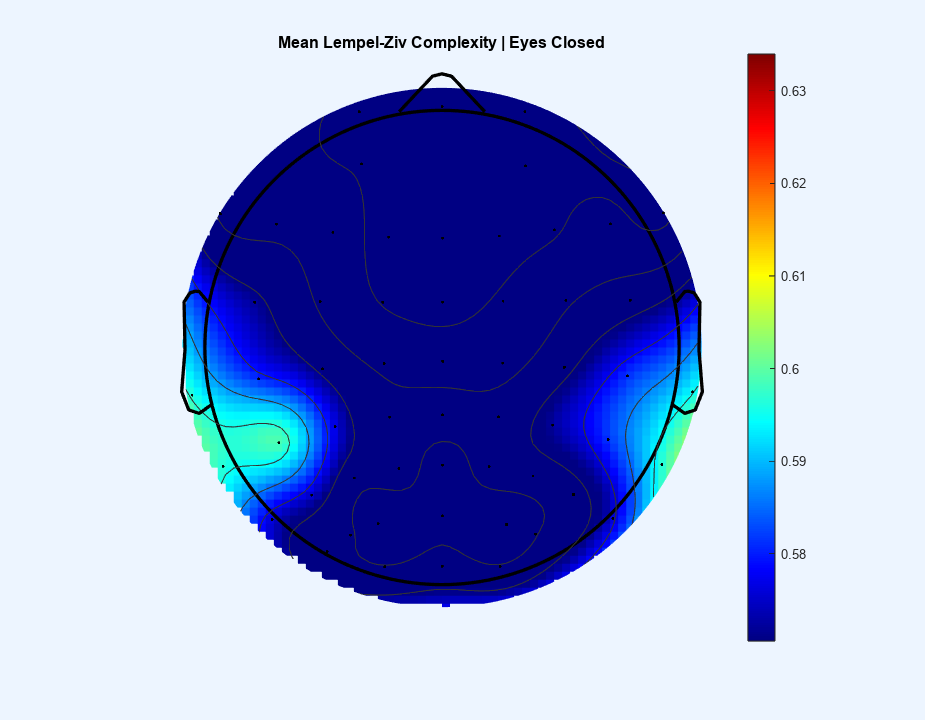

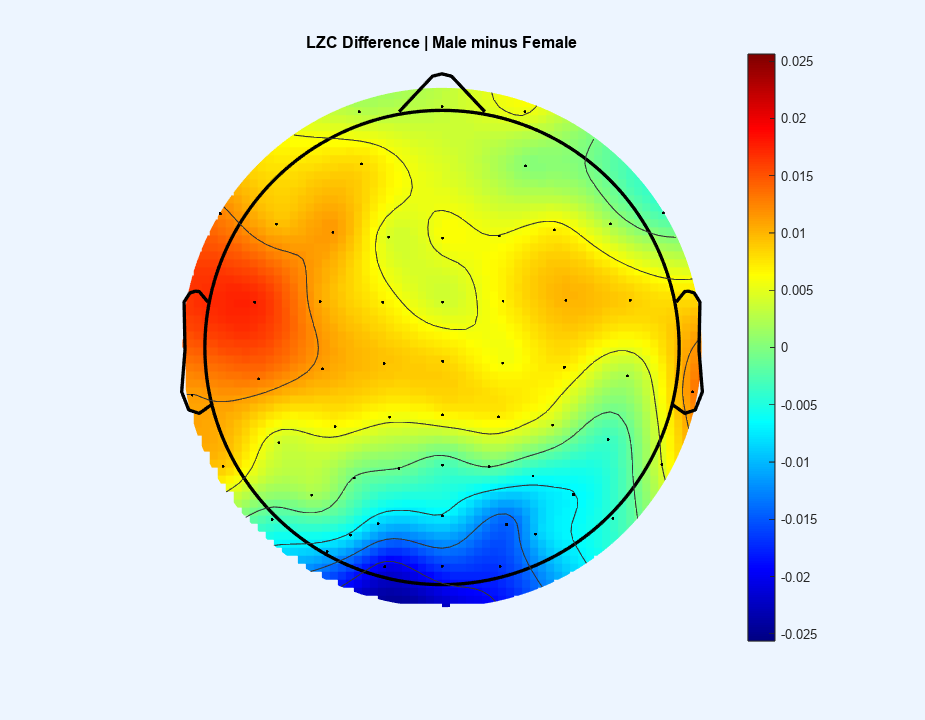

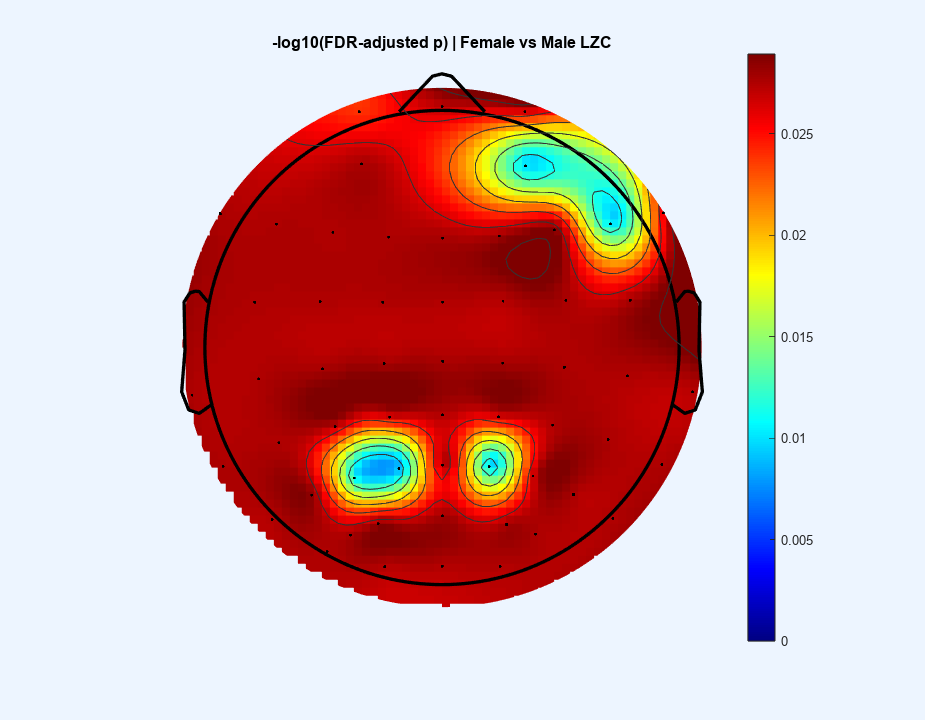

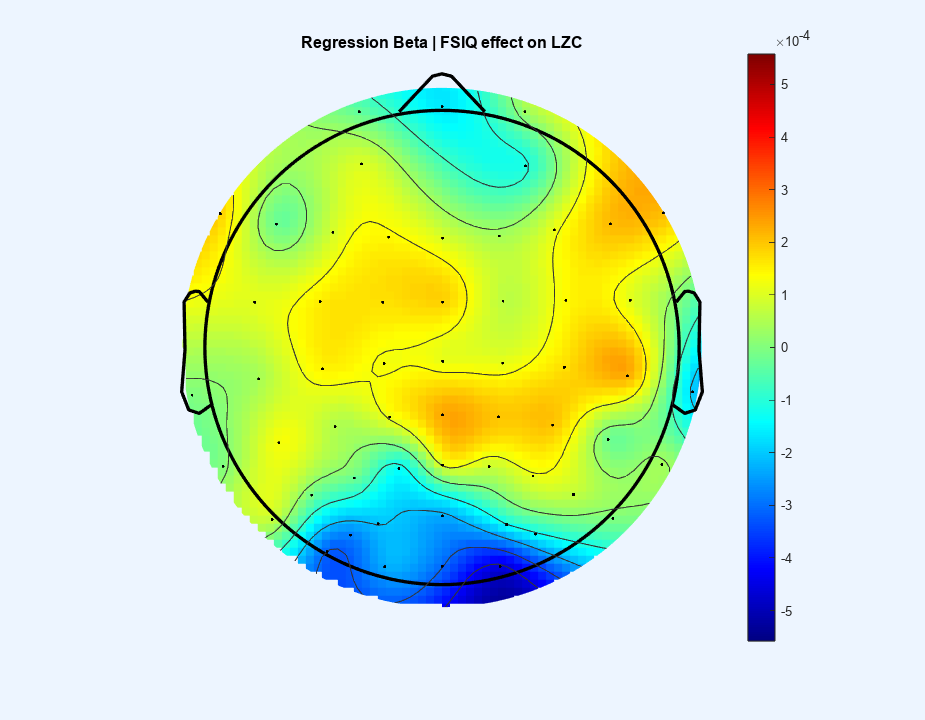

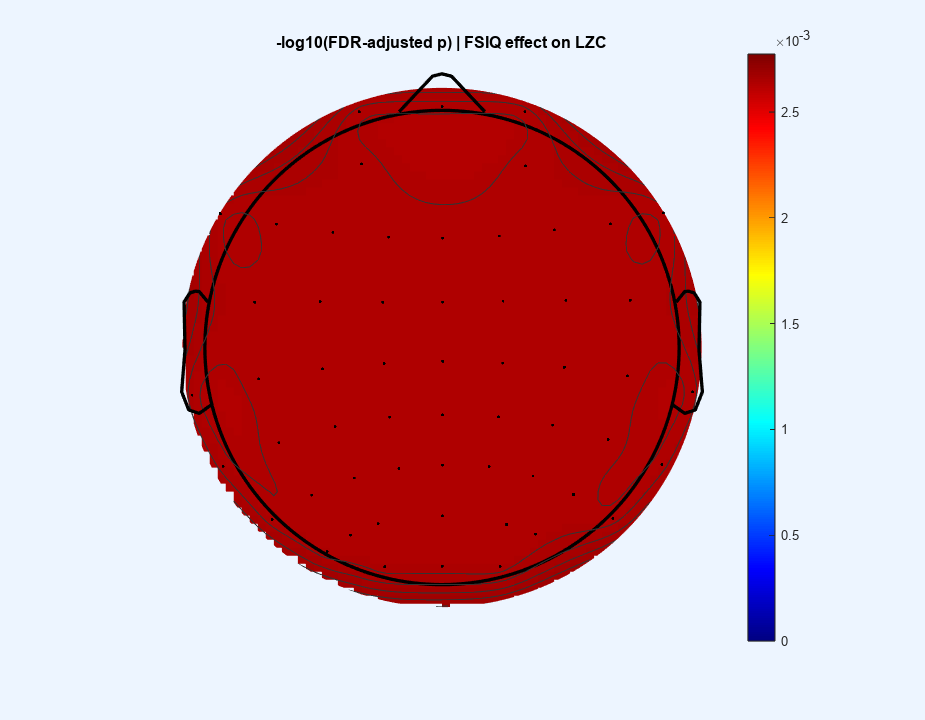

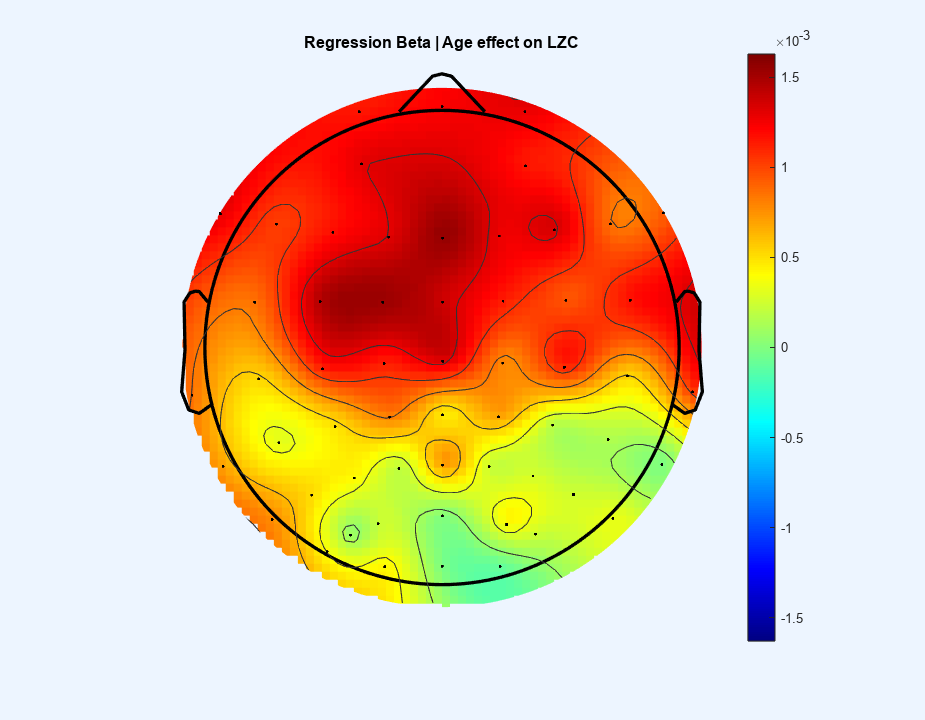


sigAge = regressionResults.P_Age_FDR < alphaFDR;
disp(regressionResults(sigAge,:));

%% ========================================================================
% 15. TOPOGRAPHIES
% ========================================================================

if makeTopographies

    %% --------------------------------------------------------------------
    % A. Mean LZC
    %% --------------------------------------------------------------------

    meanLZC = mean(LZC_all, 1, 'omitnan');

    if any(isfinite(meanLZC))

        figure('Position',[100 100 900 700], 'Color','w');

        topoplot(meanLZC, loc57, ...
            'electrodes','on', ...
            'style','both', ...
            'maplimits','maxmin');

        colorbar;
        title('Mean Lempel-Ziv Complexity | Eyes Closed');

        print(gcf, 'LZC_mean_topography.png', '-dpng', '-r300');

    end

    %% --------------------------------------------------------------------
    % B. Female vs Male effect size
    % Positive = Male > Female
    %% --------------------------------------------------------------------

    genderMap = genderDifference;
    genderMap(~isfinite(genderMap)) = 0;

    if any(isfinite(genderDifference))

        figure('Position',[100 100 900 700], 'Color','w');

        topoplot(genderMap, loc57, ...
            'electrodes','on', ...
            'style','both', ...
            'maplimits','absmax');

        colorbar;
        title('LZC Difference | Male minus Female');

        print(gcf, 'LZC_gender_difference_topography.png', ...
            '-dpng', '-r300');

    end

    %% --------------------------------------------------------------------
    % C. Gender adjusted p-values
    %% --------------------------------------------------------------------

    localPlotNegLogP( ...
        genderPFDR, ...
        loc57, ...
        maxNegLogPForPlot, ...
        '-log10(FDR-adjusted p) | Female vs Male LZC', ...
        'LZC_gender_pvalues_topography.png');

    %% --------------------------------------------------------------------
    % D. FSIQ regression beta
    % Positive beta = higher FSIQ associated with higher LZC
    %% --------------------------------------------------------------------

    fsIQBetaMap = Beta_FSIQ;
    fsIQBetaMap(~isfinite(fsIQBetaMap)) = 0;

    if any(isfinite(Beta_FSIQ))

        figure('Position',[100 100 900 700], 'Color','w');

        topoplot(fsIQBetaMap, loc57, ...
            'electrodes','on', ...
            'style','both', ...
            'maplimits','absmax');

        colorbar;
        title('Regression Beta | FSIQ effect on LZC');

        print(gcf, 'LZC_FSIQ_beta_topography.png', ...
            '-dpng', '-r300');

    end

    %% --------------------------------------------------------------------
    % E. FSIQ adjusted p-values
    %% --------------------------------------------------------------------

    localPlotNegLogP( ...
        P_FSIQ_FDR, ...
        loc57, ...
        maxNegLogPForPlot, ...
        '-log10(FDR-adjusted p) | FSIQ effect on LZC', ...
        'LZC_FSIQ_regression_pvalues.png');

    %% --------------------------------------------------------------------
    % F. Age regression beta
    %% --------------------------------------------------------------------

    ageBetaMap = Beta_Age;
    ageBetaMap(~isfinite(ageBetaMap)) = 0;

    if any(isfinite(Beta_Age))

        figure('Position',[100 100 900 700], 'Color','w');

        topoplot(ageBetaMap, loc57, ...
            'electrodes','on', ...
            'style','both', ...
            'maplimits','absmax');

        colorbar;
        title('Regression Beta | Age effect on LZC');

        print(gcf, 'LZC_Age_beta_topography.png', ...
            '-dpng', '-r300');

    end

end


%% ========================================================================
% 16. SAVE EVERYTHING
% ========================================================================

save('LZC_COMPLETE_RESULTS.mat', ...
    'LZC_all', ...
    'SubjectID', ...
    'GenderRaw', ...
    'GenderStandard', ...
    'GenderBinary', ...
    'Age', ...
    'FSIQ', ...
    'genderResults', ...
    'regressionResults', ...
    'qcTable', ...
    'loc57');

fprintf('\n====================================================\n');

fprintf('                  COMPLETE\n');

                  COMPLETE


fprintf('====================================================\n');


fprintf('\nFiles created:\n');


Files created:


fprintf('1. LZC_subject_channel.mat\n');

1. LZC_subject_channel.mat


fprintf('2. LZC_qc_summary.xlsx\n');

2. LZC_qc_summary.xlsx


fprintf('3. LZC_gender_results.xlsx\n');

3. LZC_gender_results.xlsx


fprintf('4. LZC_regression_results.xlsx\n');

4. LZC_regression_results.xlsx


fprintf('5. LZC_gender_results.mat\n');

5. LZC_gender_results.mat


fprintf('6. LZC_regression_results.mat\n');

6. LZC_regression_results.mat


fprintf('7. LZC_COMPLETE_RESULTS.mat\n');

7. LZC_COMPLETE_RESULTS.mat


fprintf('8. LZC_mean_topography.png\n');

8. LZC_mean_topography.png


fprintf('9. LZC_gender_difference_topography.png\n');

9. LZC_gender_difference_topography.png


fprintf('10. LZC_gender_pvalues_topography.png\n');

10. LZC_gender_pvalues_topography.png


fprintf('11. LZC_FSIQ_beta_topography.png\n');

11. LZC_FSIQ_beta_topography.png


fprintf('12. LZC_FSIQ_regression_pvalues.png\n');

12. LZC_FSIQ_regression_pvalues.png


fprintf('13. LZC_Age_beta_topography.png\n');

13. LZC_Age_beta_topography.png



fprintf('\nDone!\n');


Done!




%% ========================================================================
% LOCAL FUNCTION 1
% Lempel-Ziv Complexity: LZ76-style phrase parsing
% ========================================================================


function Cnorm = localLZC(binarySequence)

    s = logical(binarySequence(:)');
    N = numel(s);

    if N < 10
        Cnorm = NaN;
        return;
    end

    if all(s == s(1))
        Cnorm = NaN;
        return;
    end

    phraseCount = 0;
    position = 1;

    while position <= N

        remainingLength = N - position + 1;
        phraseWasFound = false;

        for phraseLength = 1:remainingLength

            currentPhrase = s(position : position + phraseLength - 1);

            previousRegionEnd = position - 1;

            % ابتدای سیگنال؛ اولین phrase
            if previousRegionEnd < phraseLength
                wasSeenBefore = false;
            else
                wasSeenBefore = false;

                for oldStart = 1:(previousRegionEnd - phraseLength + 1)

                    oldPhrase = s(oldStart : oldStart + phraseLength - 1);

                    if isequal(currentPhrase, oldPhrase)
                        wasSeenBefore = true;
                        break;
                    end

                end
            end

            % اولین phrase جدید را ثبت کن
            if ~wasSeenBefore
                phraseCount = phraseCount + 1;
                position = position + phraseLength;
                phraseWasFound = true;
                break;
            end

        end

        % حالت محافظتی
        if ~phraseWasFound
            phraseCount = phraseCount + 1;
            break;
        end

    end

    % Normalized LZC:
    % c(n) / (n / log2(n))
    Cnorm = phraseCount * log2(N) / N;

end


%% ========================================================================
% LOCAL FUNCTION 2
% Standardize gender labels
% ========================================================================

function g = localStandardizeGender(rawGender)

    rawGender = upper(strtrim(string(rawGender)));

    if any(rawGender == ["F","FEMALE","WOMAN","GIRL","زن"])
        g = "Female";

    elseif any(rawGender == ["M","MALE","MAN","BOY","مرد"])
        g = "Male";

    else
        g = "";
    end

end


%% ========================================================================
% LOCAL FUNCTION 3
% Convert cell/string/numeric Excel value to double safely
% ========================================================================

function value = localToDouble(x)

    if isnumeric(x)
        value = double(x);

    elseif iscell(x)
        value = str2double(string(x{1}));

    else
        value = str2double(string(x));
    end

end


%% ========================================================================
% LOCAL FUNCTION 4
% Benjamini-Hochberg FDR correction
% ========================================================================

function pFDR = localFDR(p)

    originalSize = size(p);

    p = p(:);

    pFDR = nan(size(p));

    valid = isfinite(p);

    pValid = p(valid);

    if isempty(pValid)
        pFDR = reshape(pFDR, originalSize);
        return;
    end

    [pSorted, sortIndex] = sort(pValid);

    m = numel(pSorted);

    adjustedSorted = pSorted .* m ./ (1:m)';

    % enforce monotonicity
    adjustedSorted = flipud(cummin(flipud(adjustedSorted)));

    adjustedSorted(adjustedSorted > 1) = 1;

    adjustedOriginalOrder = nan(size(pValid));

    adjustedOriginalOrder(sortIndex) = adjustedSorted;

    pFDR(valid) = adjustedOriginalOrder;

    pFDR = reshape(pFDR, originalSize);

end


%% ========================================================================
% LOCAL FUNCTION 5
% Safe plotting of -log10(FDR-adjusted p-values)
% ========================================================================

function localPlotNegLogP(pValues, loc57, maxNegLogP, plotTitle, outputFile)

    pValues = pValues(:)';

    valid = isfinite(pValues);

    if ~any(valid)
        warning('No valid p-values for: %s', plotTitle);
        return;
    end

    % MATLAB p-value can underflow to zero.
    % A lower bound prevents maps around 323 caused by realmin.
    safeP = pValues;
    safeP(~valid) = NaN;
    safeP(safeP < 1e-300) = 1e-300;

    negLogP = -log10(safeP);

    finiteValues = negLogP(isfinite(negLogP));

    if isempty(finiteValues)
        warning('No finite -log10(p) values for: %s', plotTitle);
        return;
    end

    colorLimit = min(max(finiteValues), maxNegLogP);

    if ~isfinite(colorLimit) || colorLimit <= 0
        colorLimit = 1;
    end

    plotMap = negLogP;
    plotMap(~isfinite(plotMap)) = 0;
    plotMap(plotMap > colorLimit) = colorLimit;

    figure('Position',[100 100 900 700], 'Color','w');

    topoplot(plotMap, loc57, ...
        'electrodes','on', ...
        'style','both', ...
        'maplimits',[0 colorLimit]);

    colorbar;
    title(plotTitle);

    print(gcf, outputFile, '-dpng', '-r300');

end